## Generate Velocity Field

Perlin Noise Settings

ammountN    =  592.5;
n_tiles     =     3;
n_octaves   =   28;
persistence = 0.56;
seed        =   36;

Simulation Settings

size        =  2068;
n_particles = 100000;
vel         = 21.88;
step        =     1;
END_TIME =     100;

Generate Grid

x = (1:size)/size-1/2;
y = transpose((1:size)/size-1/2);

Generate Perlin Noise [1]

rng(seed);
Psi_N     = zeros(size);
idxs      = 1:n_octaves;
max_amp   = sum(persistence.^(idxs-1));

for i = idxs
    N = imresize(padarray(rand(n_tiles*i), ...
                [n_tiles*i,n_tiles*i],"circular","both"), ...
                [3*size 3*size],"cubic");
    Psi_N = Psi_N + N(size+1:2*size,size+1:2*size) * ...
        persistence^(i-1)/...
        max_amp;
end
Psi_N = Psi_N/n_tiles;

Superposition of Potentials

Psi = vel*Psi_N;

Generate Velocity Field [2]    

[dPsidx,dPsidy] = gradient(Psi);
vx =   dPsidx./sqrt(dPsidx.^2+dPsidy.^2)*size;
vy =  -dPsidy./sqrt(dPsidx.^2+dPsidy.^2)*size;

Visualize Potential

%{
fig = figure('Position',[0,0,400,200]);
tiledlayout(1,2);
nexttile;
imagesc(Psi);
nexttile;
contour(transpose(Psi));
%}

## Particle Simulation

Initialization

dt = 1/60;
px = size*rand(n_particles,1);
[py,pidxs] = sort(size*rand(n_particles,1));
pc = 1:n_particles;
pc = pc(pidxs);

Simulation

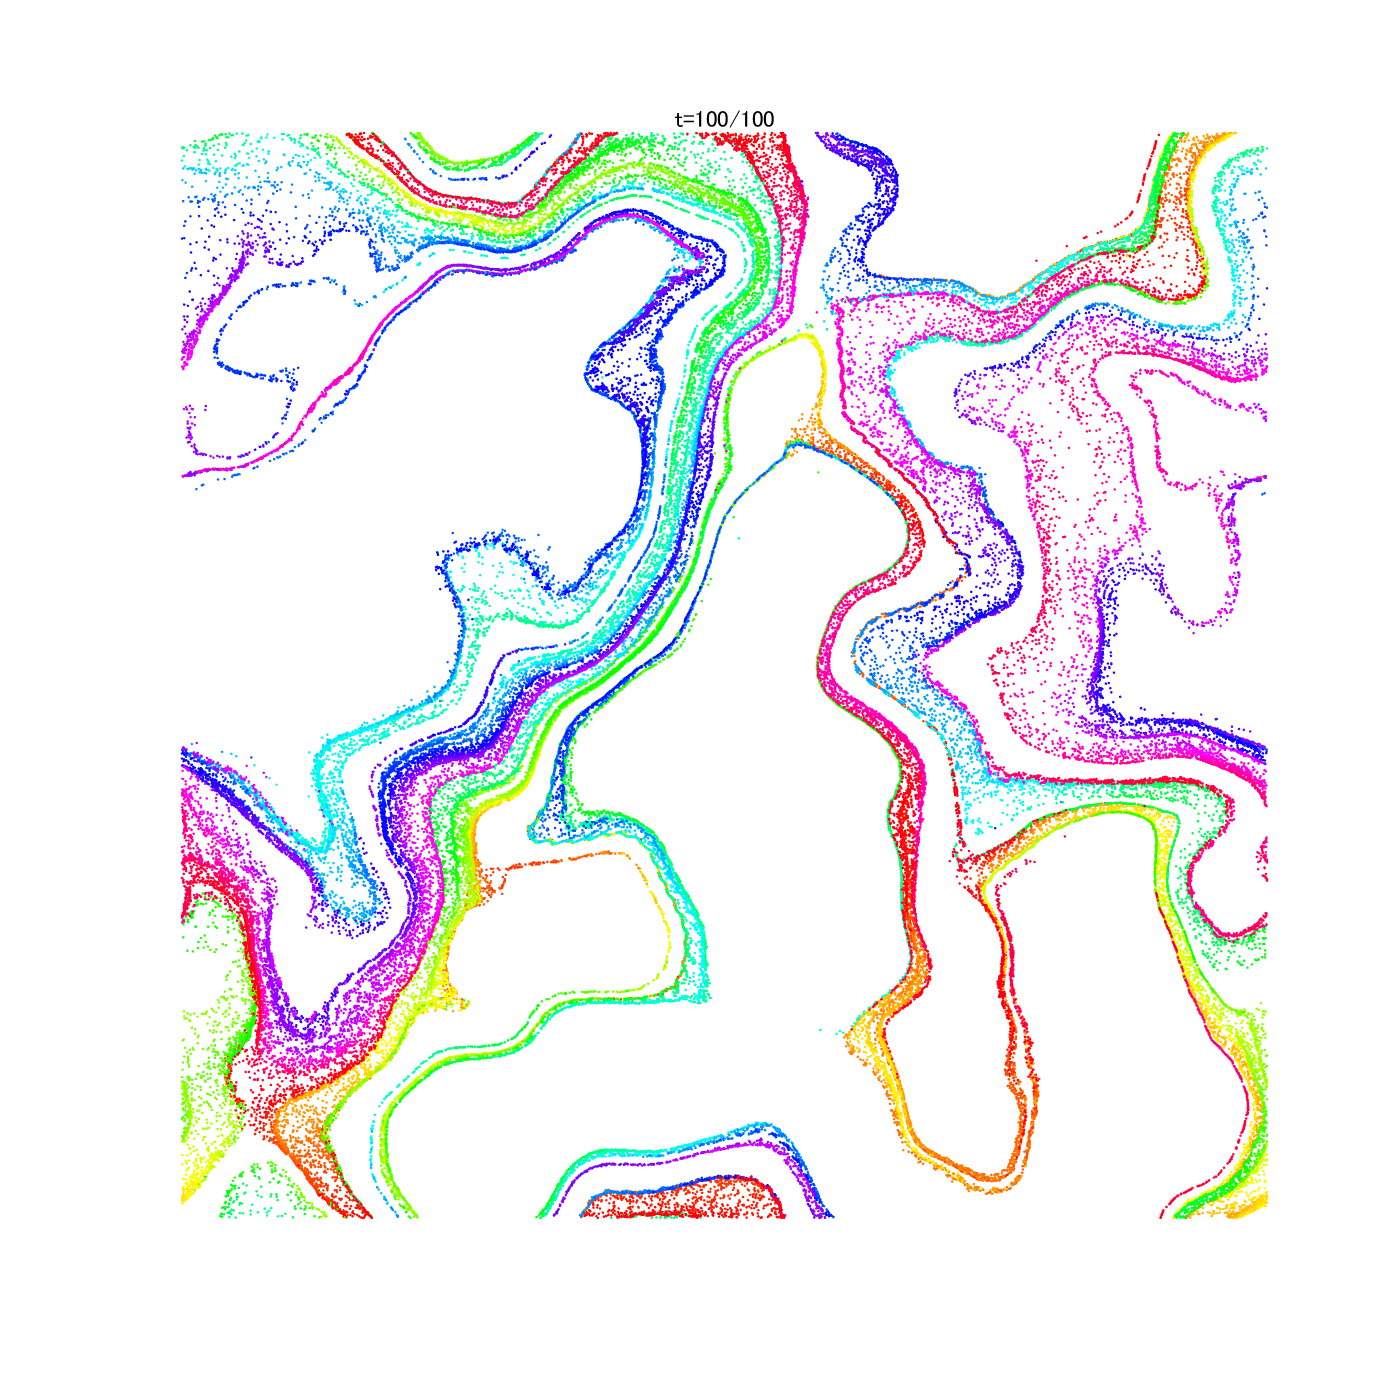

fig = figure('Position',[0,0,800,800]);
for t = 1:END_TIME*step
    
    px_grid = mod(round(px)-1,size)+1;
    py_grid = mod(round(py)-1,size)+1;
    
    px = mod(px-1,size)+1;
    py = mod(py-1,size)+1;
   
    if mod(t,step) == 0    
        cla
        hold on
        scatter(px,py,10,pc,".","CData",hsv(n_particles));
        pbaspect([1 1 1]);
        title("t="+num2str(t/step)+"/"+num2str(END_TIME));
        xlim([1,size]);
        ylim([1,size]);
        axis off
        hold off
        drawnow;
    end
        
    for i = 1:n_particles
        pvx = vx(px_grid(i),py_grid(i));
        pvy = vy(px_grid(i),py_grid(i));
        
        px(i) = px(i) + pvx * dt / step;
        py(i) = py(i) + pvy * dt / step;
    end 
end

## Reference

[1] Perlin Noise, [https://web.archive.org/web/20080724063449/http://freespace.virgin.net/hugo.elias/models/m_perlin.htm](https://web.archive.org/web/20080724063449/http://freespace.virgin.net/hugo.elias/models/m_perlin.htm)

[2] Bridson, R., Houriham, J., & Nordenstam, M. (2007). Curl-noise for procedural fluid flow. *ACM Transactions on Graphics (ToG)*, *26*(3), 46-es.